# 第一章、图像与视频处理基础

## 例1-1 显示RGB分量

请编写MATLAB程序，打开一幅RGB类型的彩色图像，分别显示R、G、B分量

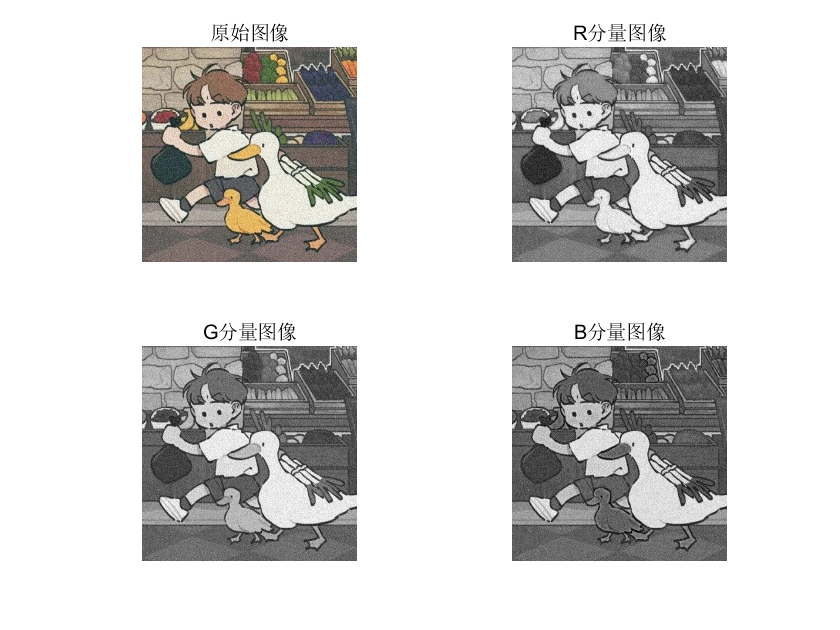

RGB=imread('pappers.png');%%读取papper图像文件
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
subplot(2,2,1);%%把界面分成2*2块，该图形占据第一块
imshow(RGB);
title('原始图像');
subplot(2,2,2);%%占据第二块
imshow(R);
title('R分量图像');
subplot(2,2,3);%%占据第三块
imshow(G);
title('G分量图像');
subplot(2,2,4);%%占据第四块
imshow(B);
title('B分量图像');

## 例1-2 读取视频、显示帧

请编写一段读取视频、显示帧，并保存每一帧的MATLAB代码

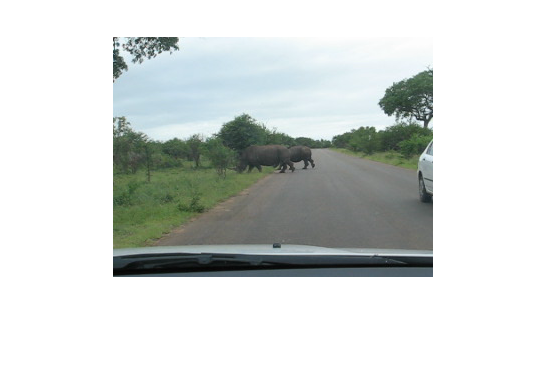

fileName='rhinos.avi';% traffic.avi  
obj=VideoReader(fileName);
numFrames=obj.NumFrames;
figure();
if exist('frame','dir')~=7
    mkdir('frames')
end
for k=1:numFrames
    frame=read(obj,k);
    imshow(frame);
    imwrite(frame,strcat('frame/',num2str(k),'.jpg'),'jpg');
end

## 例1-3 图像序列合成视频

请编写一段利用图像序列合成视频的MATLAB代码

myObj=VideoReader(fileName);
writerObj.FrameRate=30;
v = VideoWriter(strcat('new_',fileName,'.avi'),"Motion JPEG AVI");
open(v);
for i=1:numFrames
    fname=strcat('frame/',num2str(i),'.jpg');
    frame=imread(fname);
    writeVideo(v,frame);
end
close(v);